# Materials classification - A1

clear all;
clc;

## Import dataset

image_data_folder = "Data\image\";
mask_data_folder = "Data\mask\";
image = Images_import(image_data_folder);
mask = Images_import(mask_data_folder);

% Each row of each matrix contains the paths of the images of an specific material, being
% the order of the rows: fabric, foliage, glass, leather, metal, paper,
% plastic, tone, water and wood
% Now, to have acces to an image we only have to do:
% imread(image(i,j)) or imread(mask(i,j))

## Create targets

for i = 1:length(image)
    if contains(image(i).path, "fabric")
        image(i).target = "fabric";
        mask(i).target = "fabric";
    elseif contains(image(i).path, "foliage")
        image(i).target = "foliage";
        mask(i).target = "foliage";
    elseif contains(image(i).path, "glass")
        image(i).target = "glass";
        mask(i).target = "glass";
    elseif contains(image(i).path, "leather")
        image(i).target = "leather";
        mask(i).target = "leather";
    elseif contains(image(i).path, "metal")
        image(i).target = "metal";
        mask(i).target = "metal";
    elseif contains(image(i).path, "paper")
        image(i).target = "paper";
        mask(i).target = "paper";
    elseif contains(image(i).path, "plastic")
        image(i).target = "plastic";
        mask(i).target = "plastic";
    elseif contains(image(i).path, "stone")
        image(i).target = "stone";
        mask(i).target = "stone";
    elseif contains(image(i).path, "water")
        image(i).target = "water";
        mask(i).target = "water";
    elseif contains(image(i).path, "wood")
        image(i).target = "wood";
        mask(i).target = "wood";
    end
end

% Consider 1 image (original + mask) from each of classes in dataset
OrigImagesDir = ".\\Data\\image\\";
MaskImagesDir = ".\\Data\\mask\\";
fabricImgFile = OrigImagesDir + "fabric\\fabric_moderate_001_new.jpg";
fabricMaskFile = MaskImagesDir + "fabric\\fabric_moderate_001_new.jpg";
foliageImgFile = OrigImagesDir + "foliage\\foliage_final_001_new.jpg";
foliageMaskFile = MaskImagesDir + "foliage\\foliage_final_001_new.jpg";
glassImgFile = OrigImagesDir +"glass\\glass_moderate_001_new.jpg";
glassMaskFile = MaskImagesDir +"glass\\glass_moderate_001_new.jpg";
leatherImgFile = OrigImagesDir + "leather\\leather_moderate_001_new.jpg";
leatherMaskFile = MaskImagesDir + "leather\\leather_moderate_001_new.jpg";
metalImgFile = OrigImagesDir + "metal\\metal_moderate_001_new.jpg";
metalMaskFile = MaskImagesDir + "metal\\metal_moderate_001_new.jpg";
paperImgFile = OrigImagesDir + "paper\\paper_moderate_001_new.jpg";
paperMaskFile = MaskImagesDir + "paper\\paper_moderate_001_new.jpg";
plasticImgFile = OrigImagesDir + "plastic\\plastic_moderate_001_new.jpg";
plasticMaskFile = MaskImagesDir + "plastic\\plastic_moderate_001_new.jpg";
stoneImgFile = OrigImagesDir + "stone\\stone_moderate_001_new.jpg";
stoneMaskFile = MaskImagesDir + "stone\\stone_moderate_001_new.jpg";
waterImgFile = OrigImagesDir + "water\\water_moderate_001_new.jpg";
waterMaskFile = MaskImagesDir + "water\\water_moderate_001_new.jpg";
woodImgFile = OrigImagesDir + "wood\\wood_moderate_001_new.jpg";
woodMaskFile = MaskImagesDir + "wood\\wood_moderate_001_new.jpg";

fabricImgFile = imread(fabricImgFile);
fabricMaskFile = imread(fabricMaskFile);
fabricImgFile(~fabricMaskFile) = 0;
foliageImgFile = imread(foliageImgFile);
foliageMaskFile = imread(foliageMaskFile);
foliageImgFile(~foliageMaskFile) = 0;
glassImgFile = imread(glassImgFile);
glassMaskFile = imread(glassMaskFile);
glassImgFile(~glassMaskFile) = 0;
leatherImgFile = imread(leatherImgFile);
leatherMaskFile = imread(leatherMaskFile);
leatherImgFile(~leatherMaskFile) = 0;
metalImgFile = imread(metalImgFile);
metalMaskFile = imread(metalMaskFile);
metalImgFile(~metalMaskFile) = 0;
paperImgFile = imread(paperImgFile);
paperMaskFile = imread(paperMaskFile);
paperImgFile(~paperMaskFile) = 0;
plasticImgFile = imread(plasticImgFile);
plasticMaskFile = imread(plasticMaskFile);
plasticImgFile(~plasticMaskFile) = 0;
stoneImgFile = imread(stoneImgFile);
stoneMaskFile = imread(stoneMaskFile);
stoneImgFile(~stoneMaskFile) = 0;
waterImgFile = imread(waterImgFile);
waterMaskFile = imread(waterMaskFile);
waterImgFile(~waterMaskFile) = 0;
woodImgFile = imread(woodImgFile);
woodMaskFile = imread(woodMaskFile);
woodImgFile(~woodMaskFile) = 0;

% Create test image set with only the foreground image objects
testImgSet = {fabricImgFile, foliageImgFile, glassImgFile, leatherImgFile, ...
    metalImgFile, paperImgFile, plasticImgFile, stoneImgFile, waterImgFile, woodImgFile};

inputs = ["fabric", "foliage", "glass", "leather", "metal", "paper", "plastic", "stone", "water", "wood"];

## Feature Extraction

### Feature 1: Entropy measure

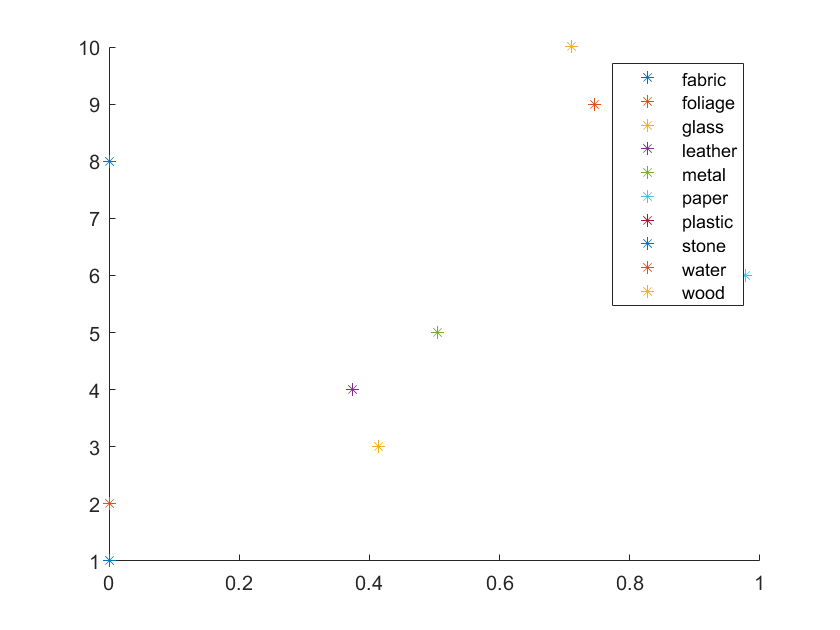

entropyVals = [];
for idx = 1:10
    entropyVals(idx) = entropy(double(im2gray(testImgSet{idx}(:))));
end
figure; hold on;
for idx = 1:10
    plot(entropyVals(idx), idx, '*');
end
legend(inputs);
hold off;

### Feature 2: Number of edges

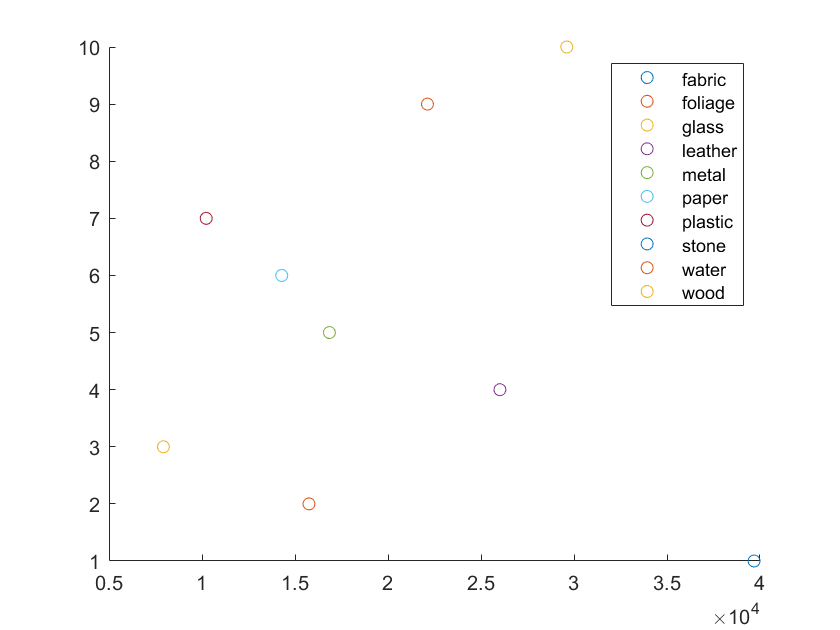

edgeCount = [];
for idx = 1:10
    bw = edge(rgb2gray(testImgSet{idx}),'canny');
    edgeCount(idx) = nnz(bw);
end

figure; hold on;
for idx = 1:10
    plot(edgeCount(idx), idx, 'o');
end
hold off;
legend(inputs);

### Feature 3: SURF features

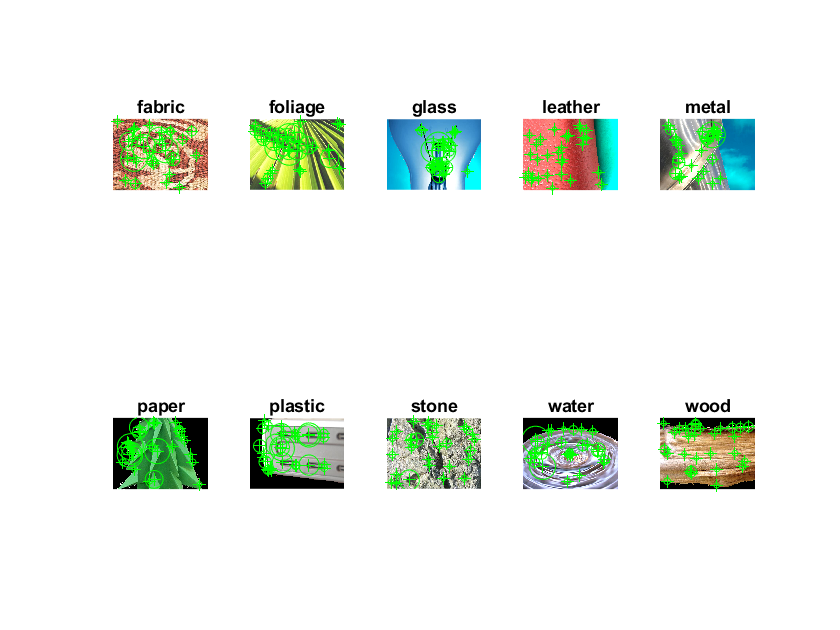

numPoints = 30;
figure;
for idx = 1:10
    points = detectSURFFeatures(rgb2gray(testImgSet{idx}));
    % Visualize the SURF features
    subplot(2,5,idx);
    imshow(testImgSet{idx}); hold on;
    plot(points.selectUniform(numPoints, size(testImgSet{idx})));
    hold off;
    title(inputs(idx));
end